# GPWHILE 

Uses a WHILE-loop to ensure that data exists for user-selected country.

See also: GPIF, GPFOR

## Load data

load gPrices

## Choose a country -- use a WHILE-loop to ask until a valid country is entered

Initialize the test variable `idx` to ensure the loop is executed at least once.

idx = false;
%  Loop until success
while ~any(idx)
    myctry = inputdlg('Enter a country: ');
    myctry = myctry{1};
    idx = strcmpi(myctry,country);
end

## Find linear fits

No need to check that data exists (guaranteed from above). 

%  Extract data for the chosen country
myPrices = Prices(:,idx);
%  Check for proper capitalization of country name
if ~strcmp(myctry,country{idx})
    warning(['Entered ',myctry,'. Modified to ',country{idx},'.'])
    myctry = country{idx};
end

%  Loop over all countries
for k = 1:length(country)
    % Find the linear fit of each country versus chosen country
    c = polyfit(myPrices,Prices(:,k),1);
    disp([country{k},'/',myctry,' slope: ',num2str(c(1))])
    ctryfit = polyval(c,myPrices);
    plot(myPrices,ctryfit)
    hold on
end

Australia/France slope: 0.69351


Canada/France slope: 0.63727


France/France slope: 1


Germany/France slope: 1.1991


Italy/France slope: 0.93439


Japan/France slope: 0.4621


Mexico/France slope: 0.24761


South Korea/France slope: 0.91372


UK/France slope: 1.1382


USA/France slope: 0.54434


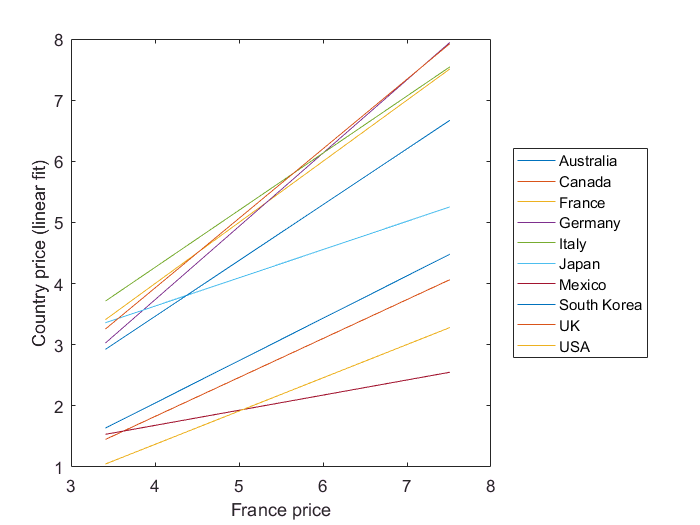

%  Annotate plot
hold off
%plot(myPrices,linfits)
xlabel([myctry,' price'])
ylabel('Country price (linear fit)')
legend(country,'location','eastoutside')